clear all
clc

opts = delimitedTextImportOptions("NumVariables", 22);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Times", "Channel5"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
digital = readtable("Measure2/digital.csv", opts)

digital = 161051×2 table
    Times     Channel5
    ______    ________

         0       0    
    2.9339       1    
    2.9409       0    
    2.9448       1    
    2.9481       0    
    2.9505       1    
    2.9529       0    
    2.9547       1    
    2.9566       0    
     2.958       1    
    2.9596       0    
    2.9608       1    
    2.9622       0    
    2.9633       1    
    2.9644       0    
    2.9654       1    





clear opts


mean = digital.Channel5(1:10001:end)

mean =      0
     1
     0
     1
     0
     1
     0
     1
     0
     1


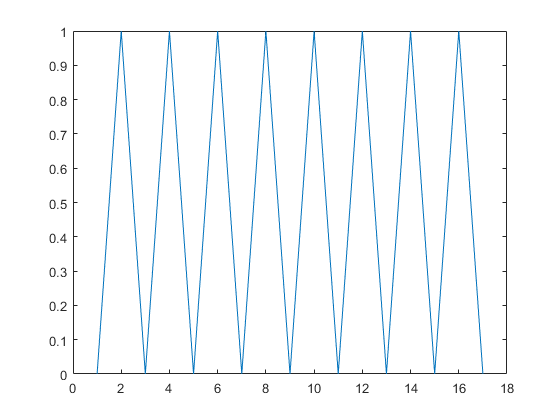


plot(mean);


t = digital.Times(digital.Channel5 == 1)

t =     2.9339
    2.9448
    2.9505
    2.9547
    2.9580
    2.9608
    2.9633
    2.9654
    2.9674
    2.9692


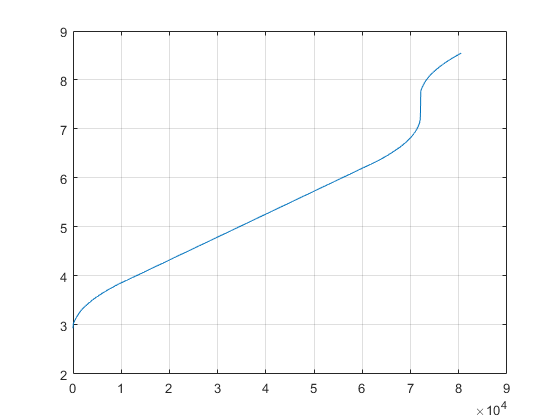


s = 2*pi/3600;
figure
plot(t);
grid on
hold off

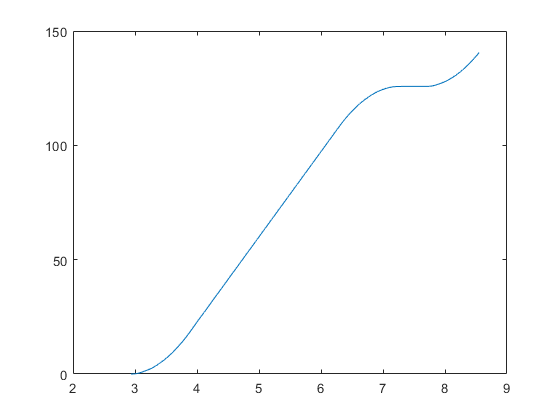

rouns = 1:length(t);
rouns= rouns * s;
rouns = rouns';
plot(t, rouns);


v = 0;
tt = 0

tt = 0

j = 1;
step = 150

step = 150

for i = 2 :step : length(t)-step
    
    dt(j) = (t(i+step)-t(i));
    tt(j) = t(i);
    v(j) = s*step/dt(j);
    j = j+1;
end

plot(tt(2:length(v)),v(2:end))
grid on
hold on


acc = 0

acc = 0

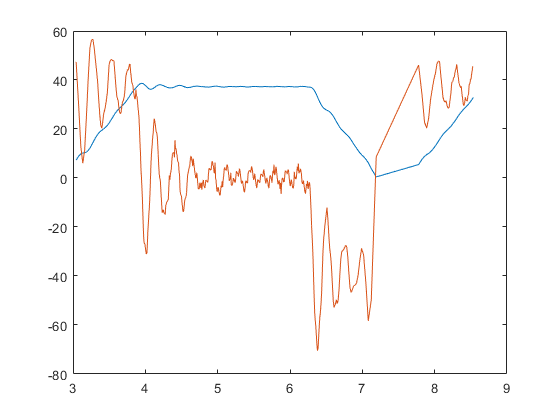

j = 1;
ttt = 0;
for i = 1: length(v)-1
    
    acc(i) = ((v(i+1)-  v(i))/ (tt(i+1) - tt(i)));

end
plot(tt(2:length(acc)), acc(2:end))
hold off
grid 



acc1 = mean(acc(1:60))

Array indices must be positive integers or logical values.


plot(acc)

Km = 0.05

Km = 0.0500

M = 2.681*10^-4

M = 2.6810e-04

sigma = M/Km

sigma = 0.0054


Is = 2/(12.2*1000)

Is = 1.6393e-04

Ds = 1200/(186*1000)

Ds = 0.0065

Ps = 40000/(11500*1000)

Ps = 0.0035


sigma = Ps

sigma = 0.0035

Kp = 11500*sigma * 1000

Kp = 40000

Kd = 186*sigma * 1000

Kd = 646.9565

ki = 12.2*sigma*1000

ki = 42.4348